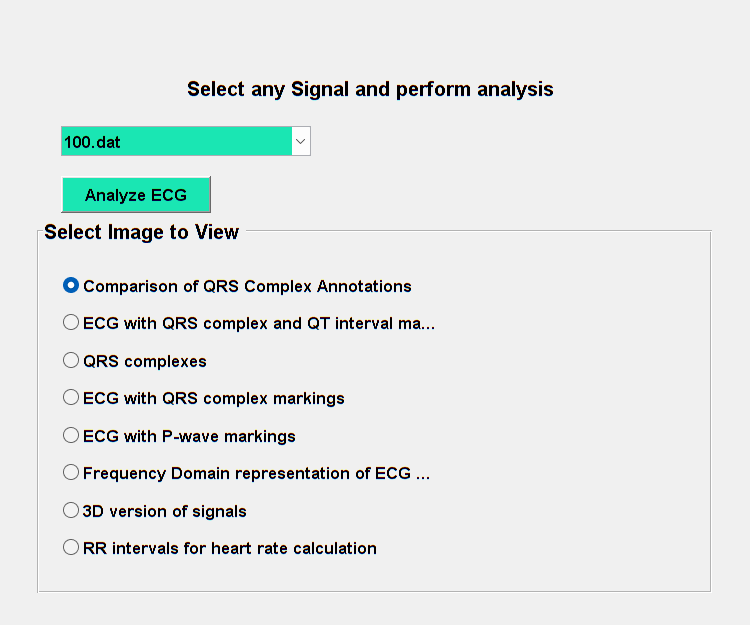

ECGAnalysisGUIWithDropdownF

[~,config]=wfdbloadlib;

display('Reading samples ECG signal from MIT-BIH Arrhythmia Database')

Reading samples ECG signal from MIT-BIH Arrhythmia Database


N=10000;
[ecg,Fs,tm]=rdsamp('mit-bih-arrhythmia-database-1.0.0/102',1,N);


% Pan-Tompkins QRS detection algorithm
%qrs_indices = pan_tompkin(ecg, Fs ,0);

[qrs_amp_raw, qrs_i_raw, ~] = pan_tompkin(ecg, Fs, 0);


display('Reading and plotting annotations (human labels) of QRS complexes performend on the signals')

Reading and plotting annotations (human labels) of QRS complexes performend on the signals


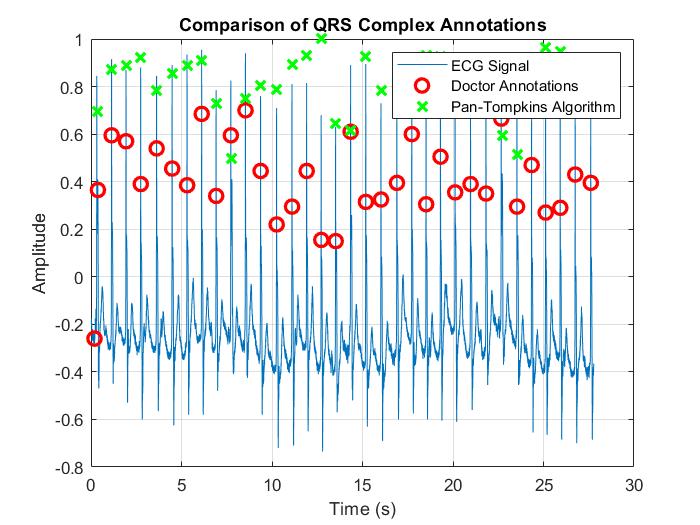

%by cardiologists.
[ann,type,subtype,chan,num]=rdann('mit-bih-arrhythmia-database-1.0.0/102','atr',1,N);
% Assuming tm is the time vector corresponding to the ECG signal
figure
plot(tm(1:N), ecg(1:N)); hold on; grid on
plot(tm(ann(ann < N) + 1), ecg(ann(ann < N) + 1), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
plot(tm(qrs_i_raw), qrs_amp_raw, 'gx', 'MarkerSize', 8, 'LineWidth', 2);
legend('ECG Signal', 'Doctor Annotations', 'Pan-Tompkins Algorithm');
xlabel('Time (s)');
ylabel('Amplitude');
title('Comparison of QRS Complex Annotations');

% Calculate RR intervals in seconds
RR_intervals = diff(qrs_i_raw) / Fs;

% Calculate heart rate in beats per minute (bpm)
heart_rate = 60 / mean(RR_intervals);

fprintf('Estimated Heart Rate: %.2f bpm\n', heart_rate);

Estimated Heart Rate: 72.66 bpm


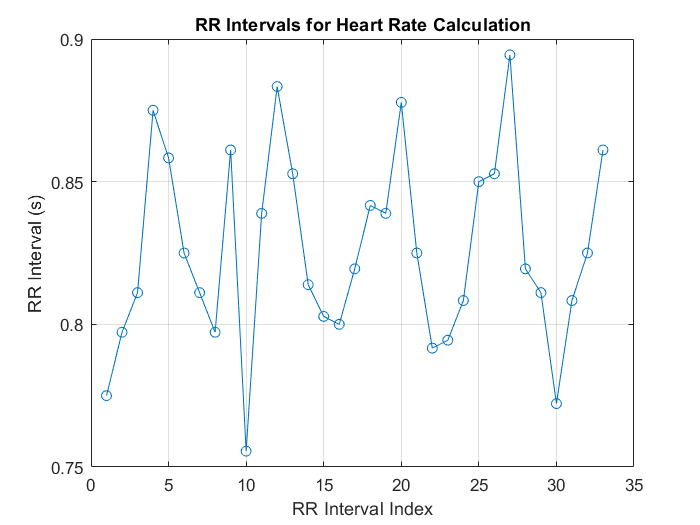


% Plot RR intervals for visualization
figure;
plot(RR_intervals, '-o');
xlabel('RR Interval Index');
ylabel('RR Interval (s)');
title('RR Intervals for Heart Rate Calculation');
grid on;


%Stack the ECG signals based on the labeled QRSs
display('Ploting 3D version of signal and labels')

Ploting 3D version of signal and labels


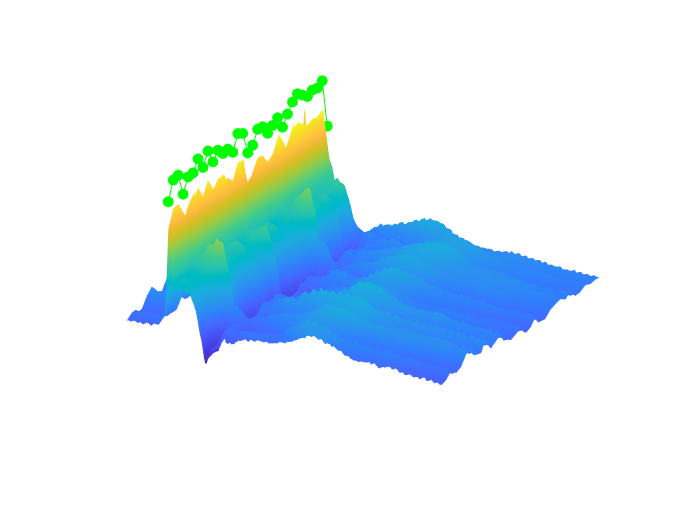

[RR,tms]=ann2rr('mit-bih-arrhythmia-database-1.0.0/102','atr',N);
delay=round(0.1/tm(2));
M=length(RR);
offset=0.3;
stack=zeros(M,min(RR))+NaN;
qrs=zeros(M,2)+NaN;
for m=1:M
    stack(m,1:min(RR)+1)=ecg(tms(m)-delay:tms(m)+min(RR)-delay);
    qrs(m,:)=[delay+1 ecg(tms(m))];
end

%Generate plot inspired by
%Clifford GD, Azuaje F, McSharry PE, editors.
%Advanced Methods and Tools for ECG Analysis.
%1st ed., Norwood, MA, USA: Artech House; 2006. (Engineering in Medicine and Biology; 1).
figure
[X,Y] = meshgrid(1:min(RR)+1,1:M);
surf(Y,X,stack);hold on;grid on
shading interp
plot3(1:M,qrs(:,1),qrs(:,2)+offset,'go-','MarkerFaceColor','g')
view(120, 30);
axis off

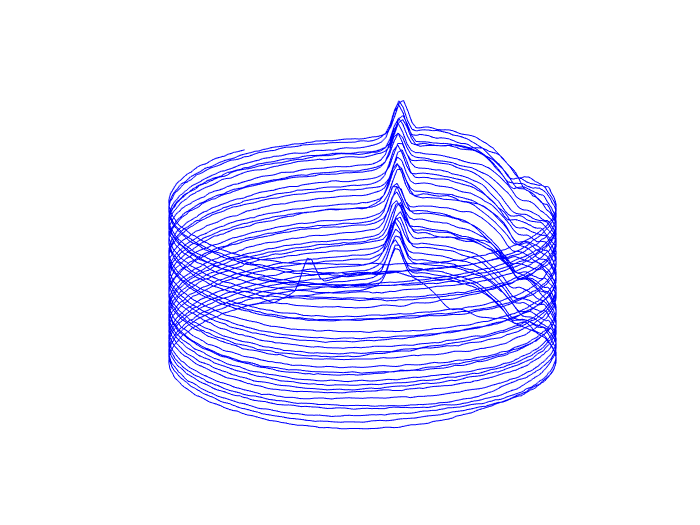


%Generate plot inspired by
% Samenie et al
% "Filtering Noisy ECG Signals Using Extended Kalman Filter Based on a
% Modified Dynamic ECG Model"
% Computers in Cardiology, 2005
figure
stack=stack';
stack=stack(:)+[0:length(stack(:))-1]'.*0.0005;
theta=linspace(0,M*2*pi,length(stack));
x=sin(theta);y=cos(theta);
plot3(x,y,stack,'b')
grid on
axis off

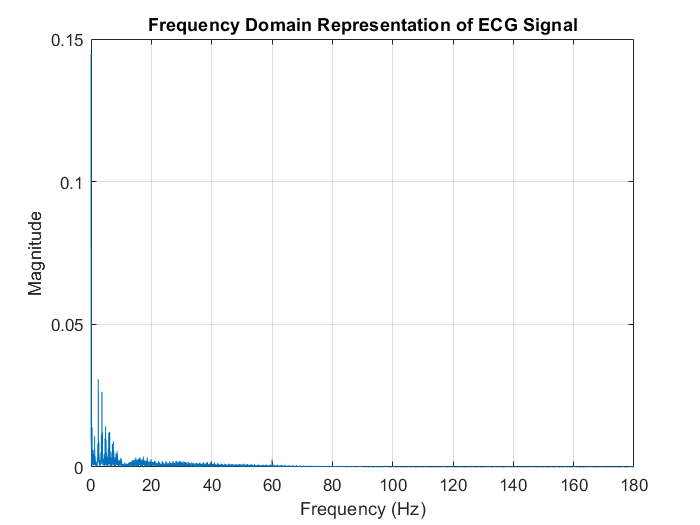

% Working in frequency domain

% Compute the FFT
NFFT = 2^nextpow2(length(ecg)); % Compute FFT length based on the signal length
Y = fft(ecg, NFFT); % Compute the FFT of the ECG signal
Y = Y(1:NFFT/2); % We only need a one-sided FFT plot
Y_abs = 1/NFFT*abs(Y); % Calculate the magnitude and normalize the spectrum

% Scale the frequency axis and calculate the corresponding frequencies
f_fft = (0:NFFT/2-1)*Fs/NFFT;

% Plot the frequency domain representation
figure
plot(f_fft, Y_abs);
title('Frequency Domain Representation of ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Add grid lines for better readability
grid on;

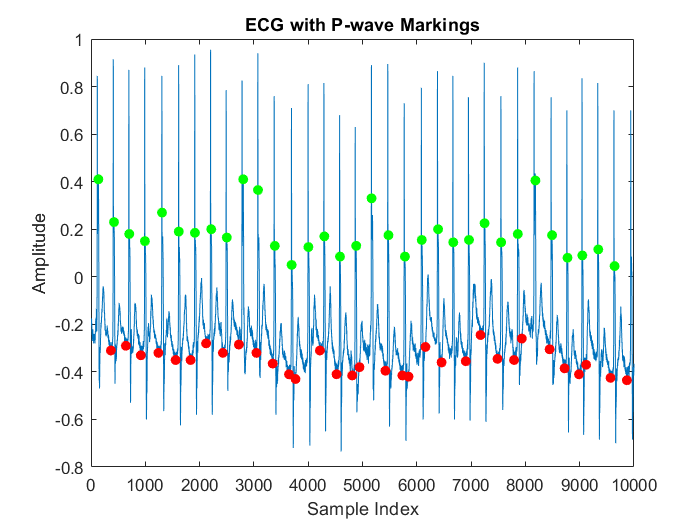


% Extract P-waves and PR intervals
p_wave_start = zeros(1, length(qrs_i_raw)-1);
p_wave_end = zeros(1, length(qrs_i_raw)-1);
pr_intervals = zeros(1, length(qrs_i_raw)-1);

for i = 1:length(qrs_i_raw)-1
    % Define a window around the QRS complex
    qrs_start = qrs_i_raw(i);
    qrs_end = qrs_i_raw(i+1);
    
    % Extract the region between QRS complexes
    ecg_segment = ecg(qrs_start:qrs_end);
    
    % Find the P-wave: you may need to adjust this based on your data
    [~, p_wave_index] = max(ecg_segment(1:round(0.2*Fs)));
    p_wave_start(i) = qrs_start + p_wave_index - 1;
    
    % Find the end of the P-wave: you may need to adjust this based on your data
    [~, p_wave_end_index] = min(ecg_segment(round(0.2*Fs):end));
    p_wave_end(i) = qrs_start + round(0.2*Fs) + p_wave_end_index - 2;
    
    % Calculate PR interval
    pr_intervals(i) = p_wave_start(i) - p_wave_end(i);
end

% Plot the ECG signal with P-wave markings
figure;
plot(ecg); hold on;
scatter(p_wave_start, ecg(p_wave_start), 'g', 'filled');
scatter(p_wave_end, ecg(p_wave_end), 'r', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('ECG with P-wave Markings');


% Display PR intervals
fprintf('Mean PR Interval: %.2f ms\n', mean(pr_intervals) * 1000);

Mean PR Interval: -197515.15 ms


fprintf('Standard Deviation of PR Intervals: %.2f ms\n', std(pr_intervals) * 1000);

Standard Deviation of PR Intervals: 70327.86 ms


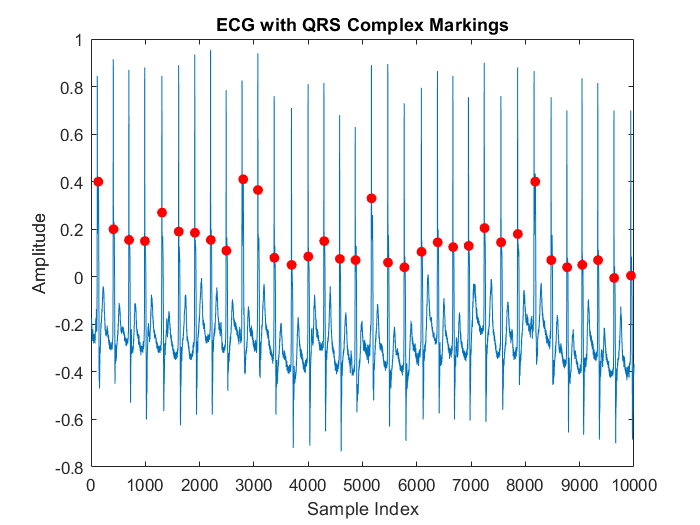

% Assess QRS complex width and morphology
qrs_widths = zeros(1, length(qrs_i_raw));
qrs_morphologies = cell(1, length(qrs_i_raw));

for i = 1:length(qrs_i_raw)
    % Define a window around the QRS complex
    qrs_start = qrs_i_raw(i) - round(0.1*Fs);
    qrs_end = qrs_i_raw(i) + round(0.2*Fs);
    
    % Ensure the window is within the signal boundaries
    qrs_start = max(qrs_start, 1);
    qrs_end = min(qrs_end, length(ecg));
    
    % Extract the QRS complex
    qrs_complex = ecg(qrs_start:qrs_end);
    
    % Calculate QRS complex width
    qrs_widths(i) = length(qrs_complex) / Fs;
    
    % Store QRS complex morphology
    qrs_morphologies{i} = qrs_complex;
end

% Plot the ECG signal with QRS complex markings
figure;
plot(ecg); hold on;
scatter(qrs_i_raw, ecg(qrs_i_raw), 'r', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('ECG with QRS Complex Markings');


% Display QRS complex widths
fprintf('Mean QRS Complex Width: %.2f ms\n', mean(qrs_widths) * 1000);

Mean QRS Complex Width: 301.39 ms


fprintf('Standard Deviation of QRS Complex Widths: %.2f ms\n', std(qrs_widths) * 1000);

Standard Deviation of QRS Complex Widths: 8.10 ms


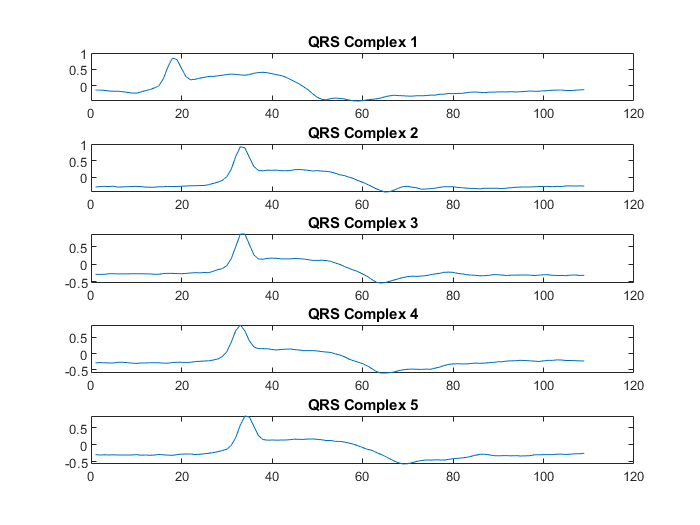


% Plot a sample of QRS complexes for morphology assessment
figure;
for i = 1:min(5, length(qrs_i_raw))
    subplot(5, 1, i);
    plot(qrs_morphologies{i});
    title(['QRS Complex ' num2str(i)]);
end

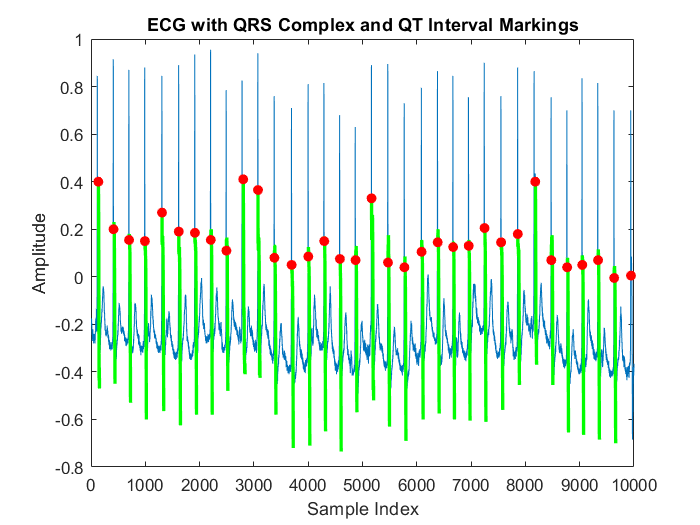

% Measure QT interval
qt_intervals = zeros(1, length(qrs_i_raw));

% Plot the ECG signal
figure;
plot(ecg); hold on;

for i = 1:length(qrs_i_raw)-1
    % Define a window around the QRS complex
    qrs_start = qrs_i_raw(i);
    qrs_end = qrs_i_raw(i+1);
    
    % Ensure the window is within the signal boundaries
    qrs_start = max(qrs_start, 1);
    qrs_end = min(qrs_end, length(ecg));
    
    % Extract the region after the QRS complex (assumption: QT interval follows QRS complex)
    qt_interval = ecg(qrs_i_raw(i)+1 : qrs_end);
    
    % Identify the end of the T-wave (you may need to adjust this based on your data)
    [~, t_wave_end_index] = min(qt_interval);
    t_wave_end = qrs_i_raw(i) + t_wave_end_index;
    
    % Calculate QT interval duration
    qt_intervals(i) = t_wave_end - qrs_i_raw(i);
    
    % Mark QT interval on the ECG signal plot
    plot(qrs_i_raw(i):t_wave_end, ecg(qrs_i_raw(i):t_wave_end), 'g', 'LineWidth', 2);
end

% Mark QRS complexes
scatter(qrs_i_raw, ecg(qrs_i_raw), 'r', 'filled');

xlabel('Sample Index');
ylabel('Amplitude');
title('ECG with QRS Complex and QT Interval Markings');


% Display QT interval durations
fprintf('Mean QT Interval: %.2f ms\n', mean(qt_intervals) * 1000);

Mean QT Interval: 27235.29 ms


fprintf('Standard Deviation of QT Intervals: %.2f ms\n', std(qt_intervals) * 1000);

Standard Deviation of QT Intervals: 6110.39 ms
